# Identify Objects Within Live Video Using ResNet-50 on Raspberry Pi Hardware

This example shows you how to predict the objects in a live video stream on Raspberry Pi® by deploying an image classification algorithm using MATLAB® Support Package for Raspberry Pi Hardware. The algorithm uses ResNet-50 neural network to identify the objects captured by the webcam that is connected to the Raspberry Pi hardware. 

When you generate code for prediction, the Raspberry Pi support package builds the executable on the hardware. Using ResNet-50, the executable classifies images into 1000 object categories, such as keyboard, coffee mug, pencil, and animals. The executable then outputs a label for the object in the image along with the probabilities for each of the object categories.   

You can experiment with objects in your surroundings to see how accurately ResNet-50 classifies images on the Raspberry Pi hardware.

Note: You cannot generate and deploy deep learning code on Raspberry Pi hardware using macOS.

## Required Hardware

- Raspberry Pi hardware (Model 4 recommended)

- A supported [USB webcam](https://elinux.org/RPi_USB_Webcams) or a [Raspberry Pi camera module](https://www.raspberrypi.com/products/camera-module-v2/)

- USB cable

- Power supply

- Ethernet cable

- A monitor connected to the Raspberry Pi hardware and a HDMI cable (optional)

## Prerequisite

Configure the Raspberry Pi network, using the [Hardware Setup](docid:mlsupportpkg#mw_15be2b78-0309-4049-975e-bf776a054522.mw_ce00da2f-bde9-4f39-a69a-a9aaf014dbc0) screen. During this process, ensure that you download the MathWorks® Raspbian image for deep learning. Instead of the MathWorks Raspbian image, if you choose to customize an existing image on your hardware, ensure that you select the option to install the ARM Compute Library.

## **Step 1: Connect the Raspberry Pi Hardware**

**Tip**: Before you start this example, we recommend you complete the [Getting Started with MATLAB Support Package for Raspberry Pi Hardware](docid:mlsupportpkg.example-raspi_gettingstarted) example.

Connect the power supply adapter to the board. For information on the recommended power supply for your Raspberry Pi, see [Raspberry Pi Recommended Power Supplies](https://www.raspberrypi.com/documentation/computers/raspberry-pi.html#power-supply). Wait until the PWR LED on the hardware starts blinking.

To connect a video device to the hardware, do any one of the following:

- If you have a webcam, connect the webcam to one of the USB ports on the hardware. Note that some webcams draw too much power and may require a powered USB hub.

- If you have a Raspberry Pi camera module, connect the camera module to the hardware by using a CSI cable. For information on how to connect the camera module to the hardware, follow the instructions in the manual provided by the manufacturer.

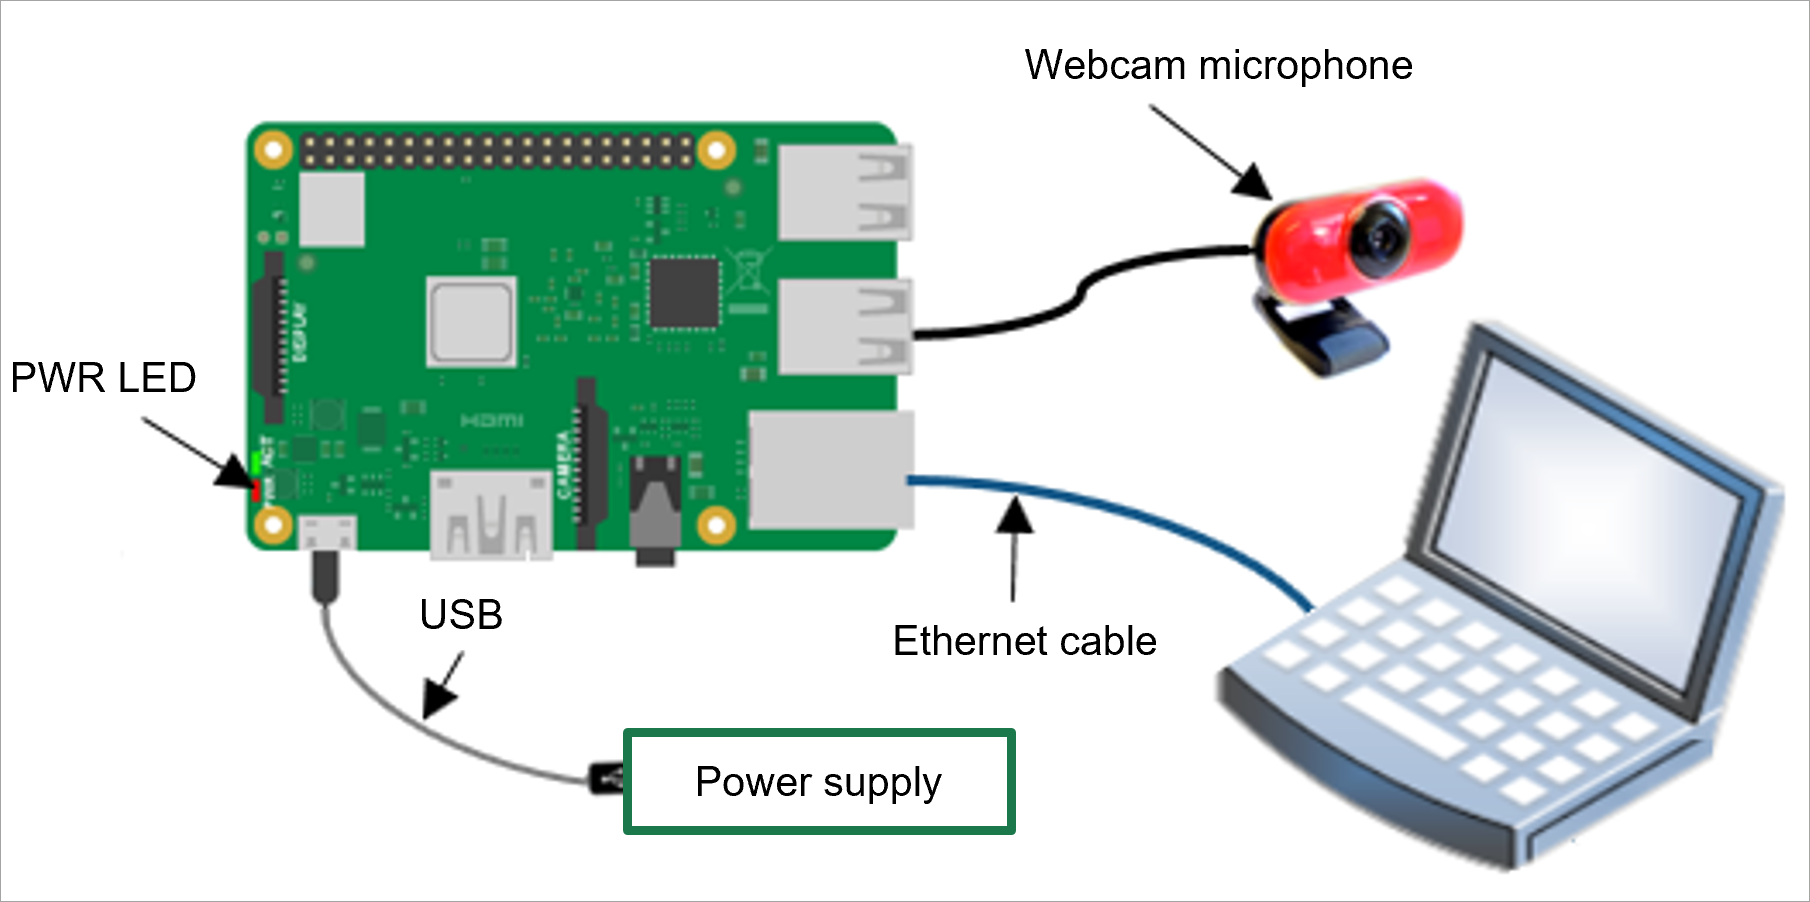

In the MATLAB Command Window, create a connection to the Raspberry Pi hardware.

r = raspi;

## Step 2: Open the Object Classification Algorithm

This example uses the ResNet-50 network to show image classification with the ARM Compute Library and returns the prediction score in the output. 

For more information on the function, enter this command in the MATLAB Command Window.

type raspi_webcam_resnet

You can modify the function by using the `edit` command.

## Step 3: **Create a Hardware Configuration Object**

Create a hardware configuration object by using the [targetHardware](docid:mlsupportpkg.mw_0826d141-e828-41a5-b465-cdf6268cb39a) function in the MATLAB Command Window.

For Raspberry Pi with 32-bit OS, use:

For Raspberry Pi with 64-bit OS, use:

board = targetHardware('Raspberry Pi (64bit)');

Verify the `DeviceAddress`, `Username`, and `Password` properties listed in the output. If required, change the value of the properties by using the dot notation syntax. For example, to change the device address to `172.18.185.123`, enter, 

Set the language of the generated code to C++ using the `TargetLang `property. 

board.CoderConfig.TargetLang = 'C++'

Create an `arm-compute `deep learning configuration object. Specify the architecture of Raspberry Pi. 

dlcfg = coder.DeepLearningConfig('arm-compute');
dlcfg.ArmArchitecture = 'armv7';

In the MATLAB Command Window, execute this command. This command displays the version of ARM Compute Library on Raspberry Pi. 

r.system('strings $ARM_COMPUTELIB/lib/libarm_compute.so | grep arm_compute_versio | cut -d\  -f 1')

Copy the version number and assign it to the `ArmComputeVersion` property of the deep learning configuration object.

dlcfg.ArmComputeVersion = '19.05';

Set the `DeepLearningConfig` property of the code generation configuration object to the deep learning configuration object.

board.CoderConfig.DeepLearningConfig = dlcfg;

## **Step 4: Deploy the Function on the Hardware**

Deploy the function as a standalone executable on the hardware by using the [deploy](docid:mlsupportpkg.mw_a8a63ef5-1af4-460a-8515-2432dd5670b6) function.

deploy(board,'raspi_webcam_resnet')

The `deploy` function initiates code generation of the `raspi_webcam_resnet` function. Once the code generation is complete, MATLAB generates a code generation report. Use this report to debug the `raspi_webcam_resnet` function for any build errors and warnings in the generated code.

After successfully generating the code, the support package loads and runs the object classification algorithm as a standalone executable on the hardware. The executable starts classifying the objects in the acquired video, and displays the predicted labels and their associated probability. To view the Raspberry Pi screen, use a VNC viewer and perform a remote session on the hardware to get the display. You can alternatively connect a HDMI cable from the monitor to the hardware.

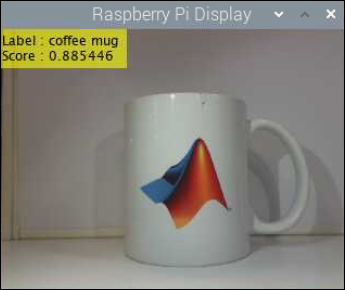

## See Also

[Classify Static Image Using Deep Learning on Raspberry Pi](docid:mlsupportpkg.example-resnet50_ssh)

*Copyright 2020 The MathWorks, Inc.*